%Lectura matriu de digits
N=1000;
[images, labels] =readMNIST( ...
    'train-images-idx3-ubyte\train-images.idx3-ubyte', ...
    'train-labels-idx1-ubyte\train-labels.idx1-ubyte',N,0);

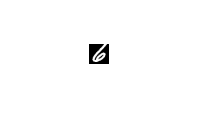


vartypes = strings([1,41]);
vartypes{41} = 'string';
vartypes(1:40) = 'double';
T = table('Size',[N 41],'VariableTypes',vartypes);




for i = 1:N
    im=images(:,:,i); 
    imshow(im)
    [sumRow, sumCol] = pixelCount(im);
    
    T{i,1:20} = sumRow;
    T{i,21:40} = sumCol;
    T.Var41(i) = labels(i);
end